# View Occlusion Sensitivity

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports GoogLeNet and a test image.

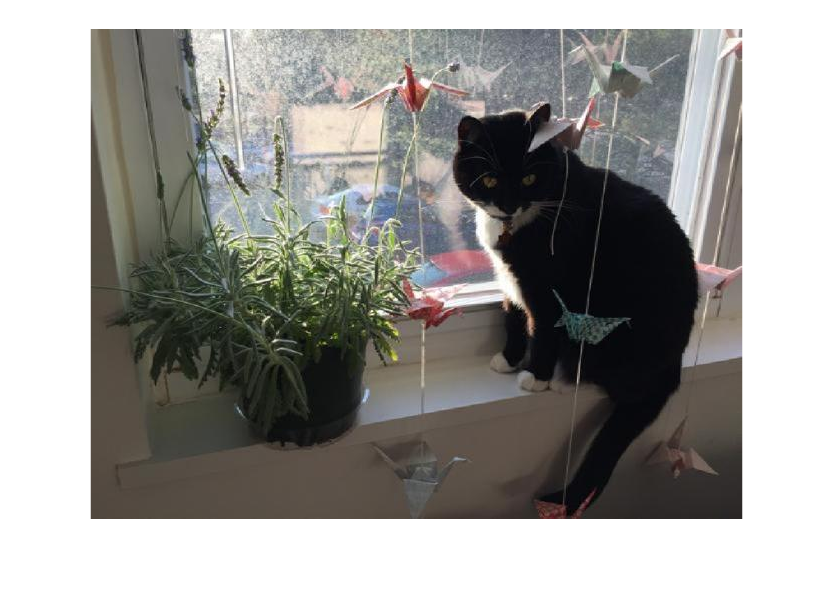

net = googlenet;
img = imread("../data/cat.jpg");
imshow(img)

## Task 1

An image `cat.jpg` has been imported. There's a few different objects in this image, including a cat, a plant, and some origami. 

img = imresize(img, [224 224]);
pred = classify(net, img)

pred = categorical
     window screen 


## Task 2

The classification is `sliding` `door`. Why did the network make that prediction? You can use a technique called occlusion sensitivity to visualize which parts of an image are important for a classification.

To calculate the occlusion sensitivity map, you'll need three inputs:

`m` `=` `occlusionSensitivity``(``net``,``I``,``label``)`

map = occlusionSensitivity(net, img, pred);

## Task 3

To view the sensitivity map, you'll overlay `map` on the cat image.

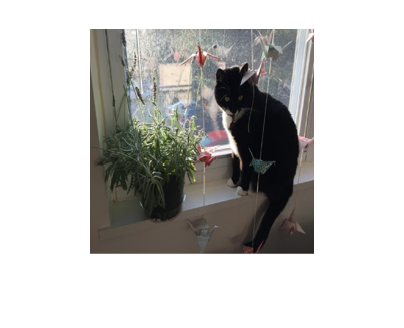

imshow(img)

## Task 4

To overlay the sensitivity map, you can use the `imagesc` function with a low alpha value.

`imagesc``(``I``,``"AlphaData"``,``a``)`

The alpha value `a` is a number from 0 to 1, where 0 transparent and 1 is opaque. 

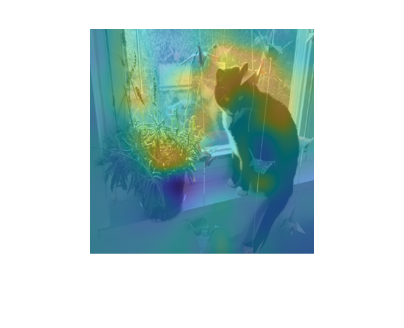

hold on
imagesc(map, "AlphaData", 0.5)
hold off

## Task 5

It is easier to see the endpoints of the sensitivity map with the `jet` colormap, which can be set with the `colormap` function:

`colormap` `jet`

You can also add a colorbar by entering `colorbar`.

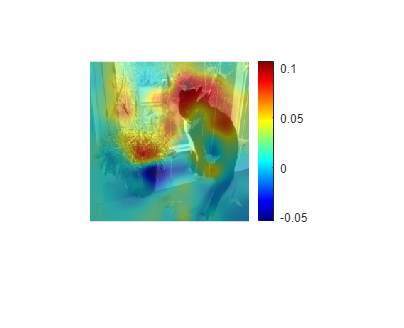

colormap jet
colorbar

## Task 6

The reddest areas of the predicted image are around the window, which explains the "sliding door" prediction.

Even though classify returns the most likely class, there were other highly probably predictions. The class `"tabby"` was network's third choice.

You can change the third input to the `occlusionSensitivity` function to another prediction to see what's important to another class.

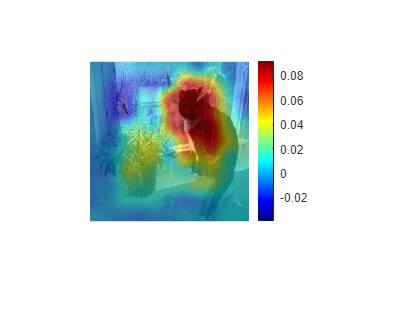

catmap = occlusionSensitivity(net, img, "tabby");
imshow(img)
hold on
imagesc(catmap, "AlphaData", 0.5)
hold off
colormap jet
colorbar